clear
% ROC curve is designed for binary classification
data = iris_dataset;
xb = data(1:2,51:150);
gnd = [-ones(1,50),ones(1,50)];
seq = randperm(100);
trainnum = 30;
Train = xb(:,seq(1:trainnum));
gnd_T = gnd(seq(1:trainnum));
Test = xb(:,seq(trainnum+1:end));
gnd_Test = gnd(seq(trainnum+1:end));

% Linear regression to compute the label
Train_aug = [ones(trainnum,1),Train'];
B = Train_aug\gnd_T'; 
Pred = [ones(100-trainnum,1),Test']*B;
test_lab = Pred>0;
test_lab = (test_lab-0.5)*2;
   
right = gnd_Test == test_lab';
% compute the accuracy
rate = sum(right)/length(gnd_Test);
disp(['Least Squares Accuracy:' num2str(rate)]);

Least Squares Accuracy:0.6


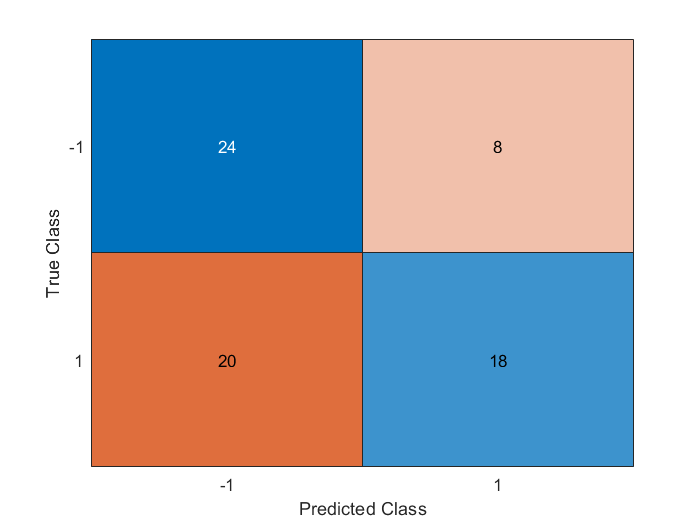


% compute the confusionmatrix
figure;
cm = confusionchart(gnd_Test,test_lab);

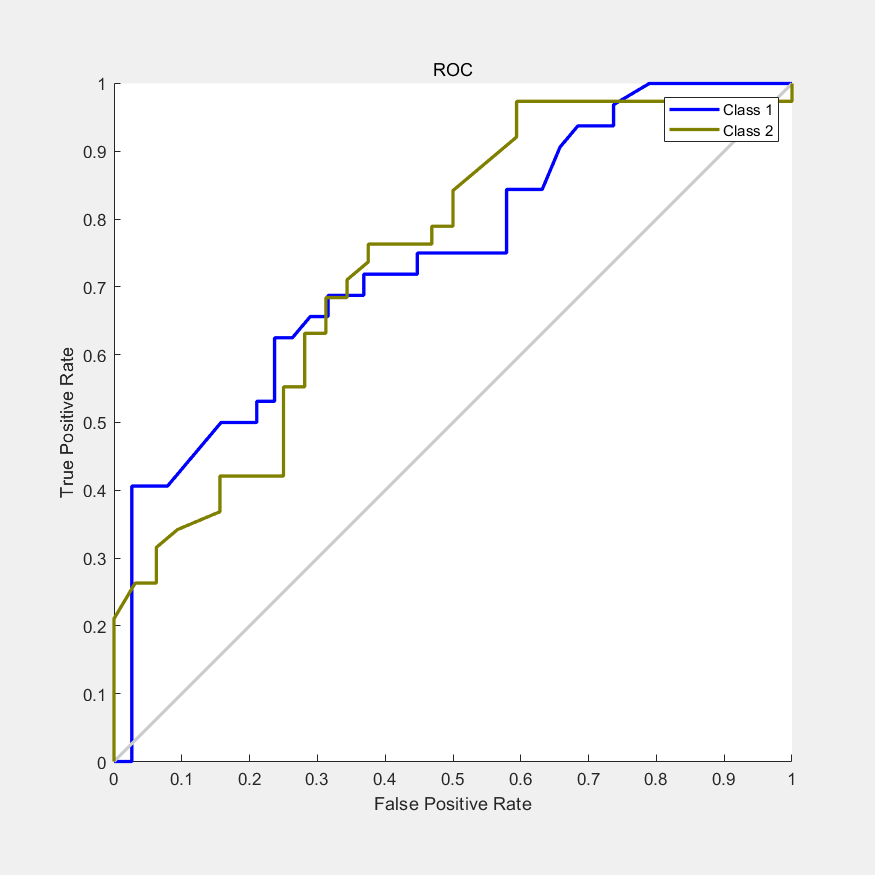


% plotroc
% in plotroc, the onehot groundtruth is neeed, and the parameter should be
% S*Q matrix according to help roc
gnd_temp = (gnd_Test+1)/2+1;
a = eye(max(gnd_temp));
gnd_onehot = a(gnd_temp,:);
Pred = (Pred - min(Pred))/(max(Pred)-min(Pred));
post_p = [1-Pred,Pred];
plotroc(gnd_onehot',post_p');